# Adaptive discount factor policy gradient

## Model

clear
clc
Q = 1;
R = 2;
A=2;
B=1;

m =1;
n=1;

## Gradient descent

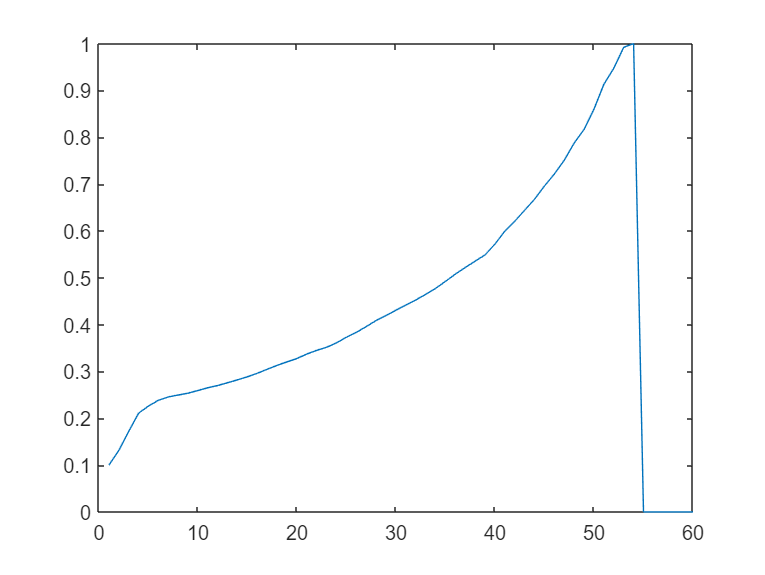

K = 0;
step = 0.00001;
num = 60;
gamma = zeros(num,1);
gamma(1) = 0.1;
cost = 0;
r = 0.0002;
for i = 1:num
    cost = oracle(K,Q,R,A,B,n,m,gamma(i));
    [alpha] = rate(Q, R, K, cost, gamma(i));
    if gamma(i)/(1-alpha) > 1
        optimal_gamma(i+1)=min(get_optimal_gamma(A,B,K),1);
        gamma(i+1) = 1;
        break
    else 
        optimal_gamma(i+1)=min(get_optimal_gamma(A,B,K),1);
        gamma(i+1) = gamma(i)/(1-alpha);
    end
    [nabla_K] = gradient(gamma(i+1),K,Q,R,A,B,n);
    [nabla_K1] = grad_eva(A,B,Q,R,r,K,gamma(i+1),n,m);
    K = K - step*nabla_K;
end
plot(gamma)